# MXB226 Case Study Modelling an Electronic Component

## Full Storage

[A,b] = full_storage;

Visualisating the Temperature from Full Storage

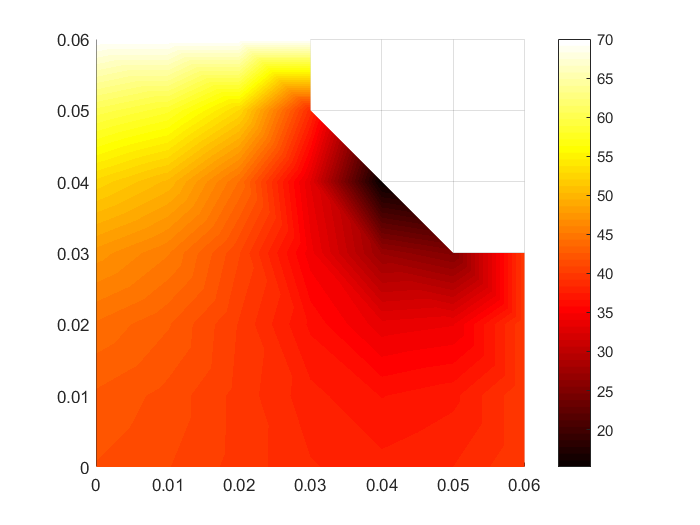

visualisation(temperatures)

## Packed Storage

%Write Code Here

Visualisating the Temperature from Packed Storage

visualisation(temperatures)

## Band Storage

%RCM Storage
%Create a new A matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);

%factorise the A matrix with cholesky factorisation
A_RCM_cholesky = cholesky(A_RCM);

%solve with forward substitution and then backwards substitution

temperatures = forward_substitution(A_RCM_cholesky', b_rcm);
temperatures = backward_substitution(A_RCM_cholesky, temperatures);
temperatures = temperatures(reorder);

Visualisating the Temperature from Band Storage

visualisation(temperatures)

## Sparse Storage

temperatures = sparseStorage(A, b);

Visualisating the Temperature from Sparse Storage

visualisation(temperatures)

## CSR Storage

clear rb;
[r,c,v] = find(A);
[r_sorted,order] = sort(r);
c = c(order);
v = v(order);

r_current = r_sorted(1);
count = 0;
rb = 1;

for i = 1:length(r_sorted)
    count = count + 1;
    if (r_sorted(i) ~= r_current)
        rb = [rb, count];
        r_current = r_sorted(i);
    end
end

% rb ends with nz + 1, where nz is the total number of nonzero elements in A.
rb = [rb, count + 1];
        

Visualisating the Temperature from CSR Storage

visualisation(temperatures)